# Frame Rotation Visualization

pa = [0 0 0];
qa = quaternion([1 0 0 0]);

pb = [0 0 0];
qb = quaternion([0 1 0 0]);

world = figure;
plot_frame(pa,qa,1);
plot_frame(pb,qb,1);

[Q,Theta,axis,delta_t,theta_coeffs] = cubicAngularTrajectory(qa,0.0,qb,0.0,1);

Q = 11×1 quaternion array
             1 +         0i +         0j +         0k
       0.99903 -  0.043968i +         0j +         0k
       0.98669 -   0.16264i +         0j +         0k
       0.94299 -   0.33282i +         0j +         0k
       0.85099 -   0.52517i +         0j +         0k
       0.70711 -   0.70711i +         0j +         0k
       0.52517 -   0.85099i +         0j +         0k
       0.33282 -   0.94299i +         0j +         0k
       0.16264 -   0.98669i +         0j +         0k
      0.043968 -   0.99903i +         0j +         0k
    6.1232e-17 -         1i +         0j +         0k


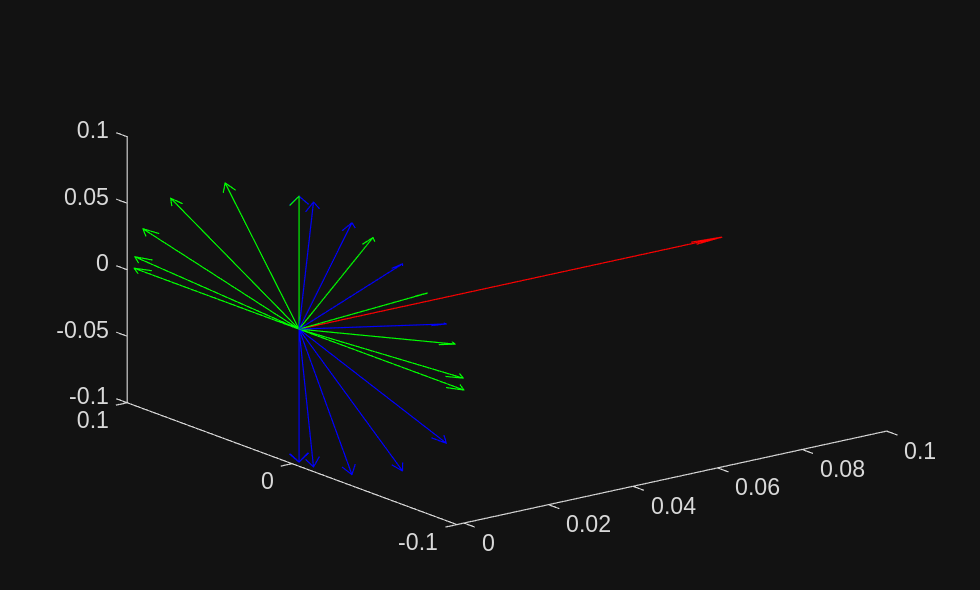


for i=[1:size(Theta',1)]
    plot_frame(pa,Q(i),1);
end